# Color transfer between images

## Color transfer will transfer the color tone from the source image to the target image.

Step 1: Input images are a source and a target image.  Display both images.

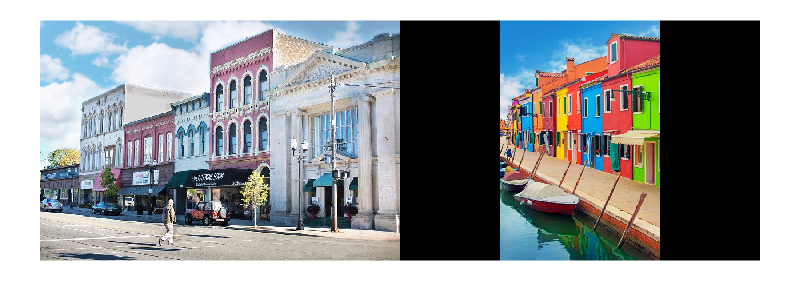

% 6388093 Nitit N.
imgsrc = imread('city_block1.png');
imgtar = imread('colorful_town1.png');
orisrc = imgsrc;
oritar = imgtar;
[Msrc,Nsrc] = size(imgsrc);
[Mtar,Ntar,Dtar] = size(imgtar);
montage({imgsrc,imgtar});

Step 2: Convert RGB to lαβ color space.  Images have size [m n 3].  You can use function "reshape" to change the size to [m*n  3]. So that we can multiply with other matrices.  

imgsrc = reshape(im2double(imgsrc),[],3);
imgtar = reshape(im2double(imgtar),[],3);

RGB2LMS = [0.3811 0.5783 0.0402 ; 0.1967 0.7244 0.0782 ; 0.0241 0.1288 0.8444];
LMS2LAB = [(1/sqrt(3)) 0 0; 0 (1/sqrt(6)) 0 ; 0 0 (1/sqrt(2))]*[1 1 1 ; 1 1 -2 ; 1 -1 0];
% LMS2LABb = ;

imgsrc = max(imgsrc,1/255);
imgsrc = RGB2LMS*imgsrc';
imgsrc = log10(imgsrc);
imgsrc = LMS2LAB*imgsrc;

imgtar = max(imgtar,1/255);
imgtar = RGB2LMS*imgtar';
imgtar = log10(imgtar);
imgtar = LMS2LAB*imgtar;

Step 3: Compute the mean and standard deviation of each of the lαβ channels for the source and target images.

imgsrc_mean = mean(imgsrc,2);
imgtar_mean = mean(imgtar,2);
imgsrc_std = std(imgsrc,0,2);
imgtar_std = std(imgtar,0,2);

Step 4: Subtract the mean of the lαβ channels of the target image from target channels.

imgtar = imgtar - imgtar_mean;

Step 5: Scale the target channels by the ratio of the standard deviation of the source divided by the standard deviation of the target, multiplied by the target channels.

imgtar = (imgsrc_std./imgtar_std).*imgtar;

Step 6: Add in the means of the lαβ channels for the source.

imgtar = imgtar + imgsrc_mean;

Step 7: Convert lαβ back to RGB color space.

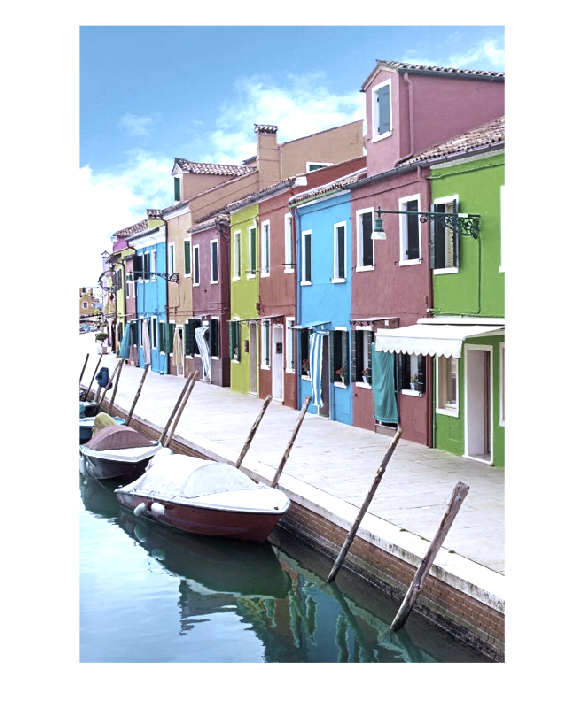

LAB2LMS = [1 1 1; 1 1 -1; 1 -2 0]* [(sqrt(3)/3) 0 0; 0 (sqrt(6)/6) 0; 0 0 (sqrt(2)/2)];
LMS2RGB = [4.4679 -3.5873 0.1193; -1.2186 2.3809 -0.1624; 0.0497 -0.2439 1.2045];
imgtar = LAB2LMS*imgtar;
imgtar = 10.^imgtar;
imgtar = (LMS2RGB*imgtar)';
img_result = reshape(imgtar(:),Mtar,Ntar,[]);
imshow(img_result);